global pt1 pt06 pt03 pt01 pt003 
load("experimental_data.mat")

warning('off')

x0_ = [0.0009    3.3145   39.8101    0.0877    0.1368   42.6416    1.6546   22.3100];

MU  = x0_(1);
ALPHA = x0_(2);
KELAS = x0_(3);
MUVIS = x0_(4);
ALPHAVIS = x0_(5);
KVIS = x0_(6);
RTIME = x0_(7);
MUVIS_2 = MUVIS;
ALPHAVIS_2 = ALPHAVIS;
KVIS_2 = KVIS;
RTIME_2 = x0_(8);
% 
x0=[MU, ALPHA, KELAS, MUVIS, ALPHAVIS, KVIS, RTIME, RTIME_2];
global xsol
xsol = zeros(size(x0));
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1, 8);
ub = [];
nonlcon = [];
penalty = 1e10;
f1 = @loss_function_lsq_2ELred_NR;
f2 = @constraint2ELred;
loss_function_lsq_cstr = @(x) f1(x) + penalty * f2(x);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9         95.1825                      3.07e+04
     1         18         95.1825        3.36027       3.07e+04      
     2         27         95.1825       0.840068       3.07e+04      
     3         36         95.1825       0.210017       3.07e+04      
     4         45         95.0761      0.0525043       2.34e+03      
     5         54         95.0761       0.105009       2.34e+03      
     6         63         95.0553      0.0262521            814      
     7         72          95.039      0.0262521            701      
     8         81         94.6877      0.0262521           95.4      
     9         90         94.4421      0.0525043            462      
    10         99         94.4421       0.105009            462      
    11        108         94.4421      0.0262521            462      
    12        117         94.227

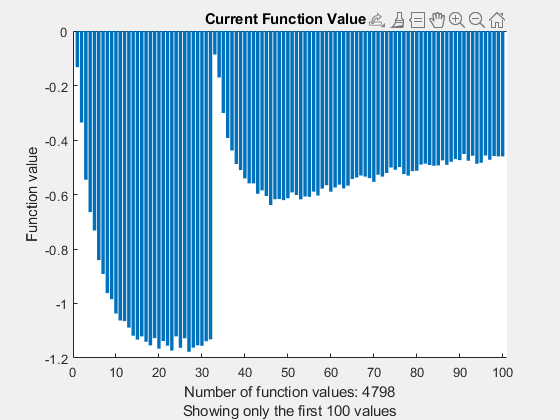


lsqnonlin stopped by the output or plot function.



x =     0.0009    3.4505   44.7767    0.1031    0.1242   53.7598    1.2832   17.7527


fval = 94.1105

exitflag =    -0.1324
   -0.3358
   -0.5458
   -0.6647
   -0.7320
   -0.8409
   -0.8917
   -0.9620
   -0.9840
   -1.0367


output = -1

options = optimset('PlotFcns',@optimplotfval, 'MaxIter', 100, 'Display','iter');
[x,fval,exitflag,output] = lsqnonlin(loss_function_lsq_cstr, x0, lb, ub, options)

global DFGRD0 STRETCH_NEW STATEV DTIME ...
MU  ALPHA  KELAS  ...
MUVIS ALPHAVIS  KVIS ETADEV ETAVOL ...
MUVIS_2 ALPHAVIS_2  KVIS_2  ETADEV_2 ETAVOL_2
optionsNR = optimoptions('fsolve','Display', 'none','FunctionTolerance', 1e-16, 'StepTolerance', 1e-16);

MU  = x(1);
ALPHA = x(2);
KELAS = x(3);
MUVIS = x(4);
ALPHAVIS = x(5);
KVIS = x(6);
RTIME = x(7);
ETADEV = RTIME * MUVIS * ALPHAVIS;
ETAVOL = RTIME * KVIS;
MUVIS_2 = MUVIS;
ALPHAVIS_2 = ALPHAVIS;
KVIS_2 = KVIS;
RTIME_2 = x(8);
ETADEV_2 = RTIME_2 * MUVIS_2 * ALPHAVIS_2;
ETAVOL_2 = RTIME_2 * KVIS_2;

 


% loss for strain rate pt1
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt1 = size(pt1);
lenpt1 = lenpt1(1);
pt1sim = zeros(lenpt1, 2);
pt1sim(1,:) = [1, 0];
for datapoint = 2:lenpt1
    STRETCH_NEW = pt1(datapoint, 2);
    DTIME = pt1(datapoint, 4) - pt1(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA2EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);

    DFGRD0 = DFGRD1;
    pt1sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt06
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt06 = size(pt06);
lenpt06 = lenpt06(1);
pt06sim = zeros(lenpt06, 2);
pt06sim(1,:) = [1, 0];
for datapoint = 2:lenpt06
    STRETCH_NEW = pt06(datapoint, 2);
    DTIME = pt06(datapoint, 4) - pt06(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA2EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);

    DFGRD0 = DFGRD1;
    pt06sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt03
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt03 = size(pt03);
lenpt03 = lenpt03(1);
pt03sim = zeros(lenpt03, 2);
pt03sim(1,:) = [1, 0];
for datapoint = 2:lenpt03
    STRETCH_NEW = pt03(datapoint, 2);
    DTIME = pt03(datapoint, 4) - pt03(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA2EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);

    DFGRD0 = DFGRD1;
    pt03sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt01
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt01 = size(pt01);
lenpt01 = lenpt01(1);
pt01sim = zeros(lenpt01, 2);
pt01sim(1,:) = [1, 0];
for datapoint = 2:lenpt01
    STRETCH_NEW = pt01(datapoint, 2);
    DTIME = pt01(datapoint, 4) - pt01(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA2EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);

    DFGRD0 = DFGRD1;
    pt01sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt003
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt003 = size(pt003);
lenpt003 = lenpt003(1);
pt003sim = zeros(lenpt003, 2);
pt003sim(1,:) = [1, 0];
for datapoint = 2:lenpt003
    STRETCH_NEW = pt003(datapoint, 2);
    DTIME = pt003(datapoint, 4) - pt003(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA2EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_2EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2);

    DFGRD0 = DFGRD1;
    pt003sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end





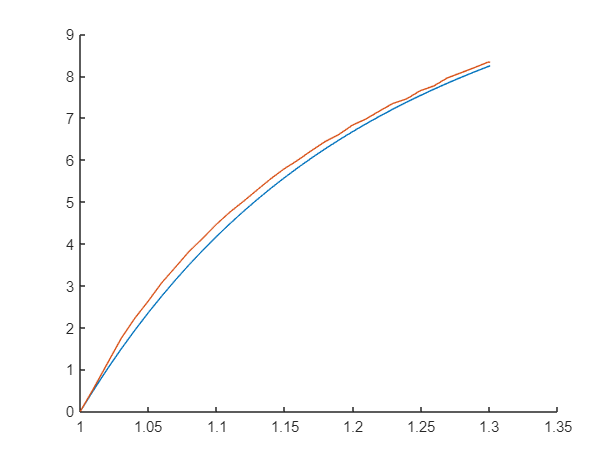

close all
hold on
plot(pt1sim(:,1), pt1sim(:,2));
plot(pt1(:,2), pt1(:,1));
hold off

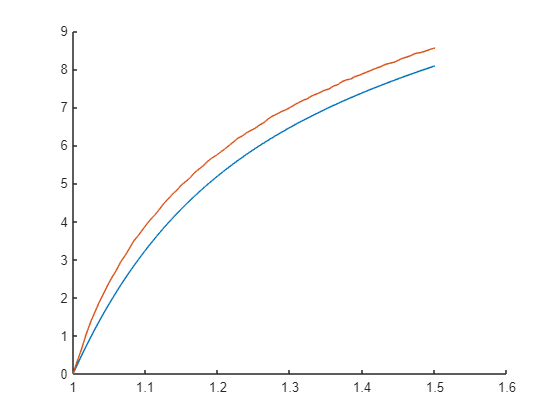

close all
hold on
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt06(:,2), pt06(:,1));
hold off

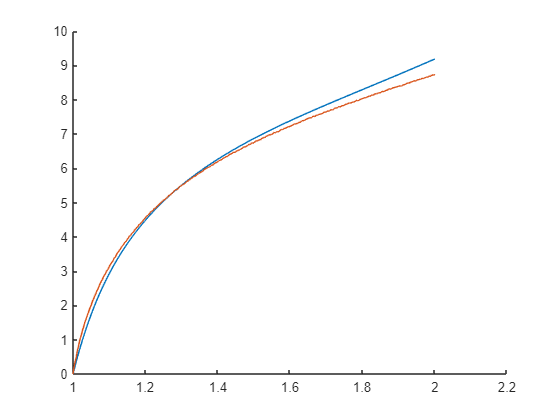

close all
hold on
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt03(:,2), pt03(:,1));
hold off

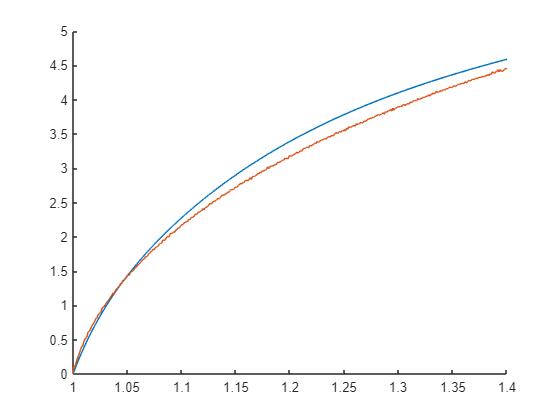

close all
hold on
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt01(:,2), pt01(:,1));
xlim([1, 1.4])
hold off

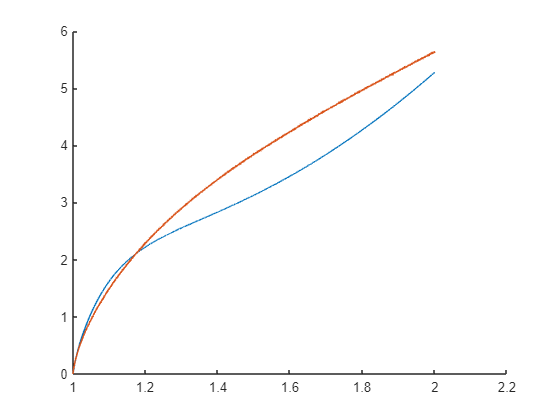

close all
hold on
plot(pt003sim(:,1), pt003sim(:,2));
plot(pt003(:,2), pt003(:,1));
hold off

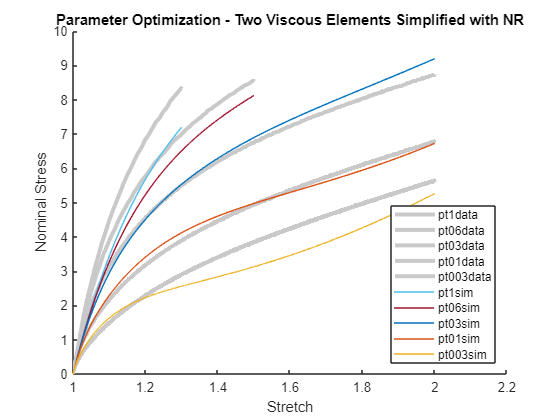

close all
hold on
plot(pt1(:,2), pt1(:,1),'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt06(:,2), pt06(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt03(:,2), pt03(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt01(:,2), pt01(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt003(:,2), pt003(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);

plot(pt1sim(:,1), pt1sim(:,2));
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt003sim(:,1), pt003sim(:,2));
legend('pt1data', 'pt06data', 'pt03data', 'pt01data', 'pt003data', 'pt1sim', 'pt06sim', 'pt03sim', 'pt01sim', 'pt003sim', 'Location', 'southeast')
xlabel('Stretch')
ylabel('Nominal Stress')
title('Parameter Optimization - Two Viscous Elements Simplified with NR')


hold off